# Experimental Methods HW #5 Dan Lawson

## Problem 1: Hot Wire Calibration

% Using Polyfit, fit the following data with a third order polynomial
% Fit with a 90% confidence 
clear

U = [0 8.38 17.27 26.08 34.83];
E = [9.52 5.22 3.76 2.81 2.06];
X = linspace(0,35,1e3);

p3 = polyfit(U, E, 3);
E_fit3 = polyval(p3, X);
E_cfit3 = polyval(p3, U);

sig_E3 = sqrt(sum((E - E_cfit3).^2)/(length(U)-4));
err3 = t_value(0.9, length(U)-4)*sig_E3

err3 = 1.7780

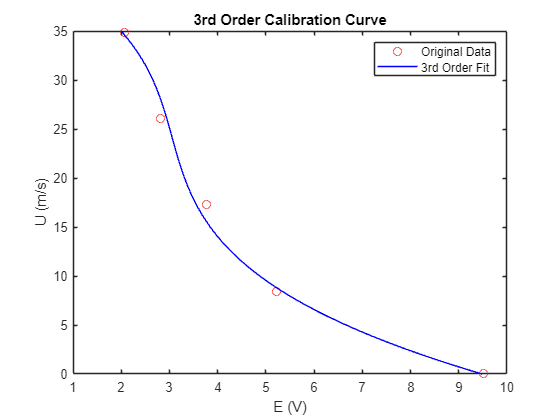


figure;

plot(E, U, 'ro', 'DisplayName', 'Original Data');
hold on;
plot(E_fit3, X, 'b-', 'DisplayName', '3rd Order Fit');
hold off;

ylabel('U (m/s)');
xlabel('E (V)');
title('3rd Order Calibration Curve');
legend('show','Location','northeast');



% Now, fit with a fourth order polynomial
% Fit with a 90% confidence
clear

U = [0 8.38 17.27 26.08 34.83];
E = [9.52 5.22 3.76 2.81 2.06];
X = linspace(0,35,1e3);

p4 = polyfit(U, E, 4);
E_fit4 = polyval(p4, X);
E_cfit4 = polyval(p4, U);

sig_E4 = sqrt(sum((E - E_cfit4).^2)/(length(U)-4));
err4 = t_value(0.9, length(U)-4)*sig_E4

err4 = 4.9048e-14

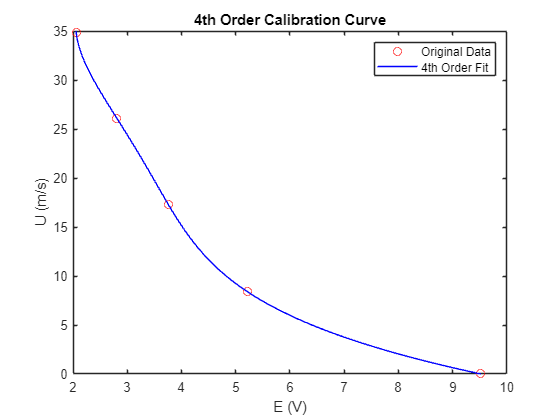


figure;

plot(E, U, 'ro', 'DisplayName', 'Original Data');
hold on;
plot(E_fit4, X, 'b-', 'DisplayName', '4th Order Fit');
hold off;

ylabel('U (m/s)');
xlabel('E (V)');
title('4th Order Calibration Curve');
legend('show','Location','northeast');


% Repeat the previous fits with additional calibration points
clear

U = [0 4.06 8.38 12.82 17.27 21.68 26.08 30.48 34.83];
E = [9.52 6.45 5.22 4.39 3.76 3.24 2.81 2.40 2.06];
X = linspace(0,35,1e3);

p3 = polyfit(U, E, 3);
E_fit3 = polyval(p3, X);
E_cfit3 = polyval(p3, U);

sig_E3 = sqrt(sum((E - E_cfit3).^2)/(length(U)-4));
err3 = t_value(0.9, length(U)-4)*sig_E3

err3 = 0.6210

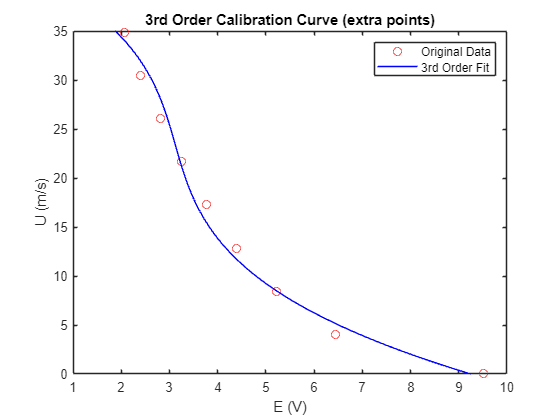


figure;

plot(E, U, 'ro', 'DisplayName', 'Original Data');
hold on;
plot(E_fit3, X, 'b-', 'DisplayName', '3rd Order Fit');
hold off;

ylabel('U (m/s)');
xlabel('E (V)');
title('3rd Order Calibration Curve (extra points)');
legend('show','Location','northeast');



% Now, fit with a fourth order polynomial
% Fit with a 90% confidence
clear

U = [0 4.06 8.38 12.82 17.27 21.68 26.08 30.48 34.83];
E = [9.52 6.45 5.22 4.39 3.76 3.24 2.81 2.40 2.06];
X = linspace(0,35,1e3);

p4 = polyfit(U, E, 4);
E_fit4 = polyval(p4, X);
E_cfit4 = polyval(p4, U);

sig_E4 = sqrt(sum((E - E_cfit4).^2)/(length(U)-4));
err4 = t_value(0.9, length(U)-4)*sig_E4

err4 = 0.2925

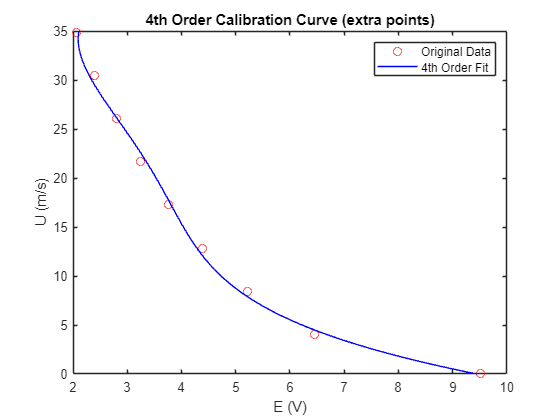


figure;

plot(E, U, 'ro', 'DisplayName', 'Original Data');
hold on;
plot(E_fit4, X, 'b-', 'DisplayName', '4th Order Fit');
hold off;

ylabel('U (m/s)');
xlabel('E (V)');
title('4th Order Calibration Curve (extra points)');
legend('show','Location','northeast');

## Problem 4: 

% For R = 10 ohms and C = 10 microF,  plot amplitude responses (in dB) as a
% function of f (in Hz), using 'semilogx' function for f = [10:10:100] kHz
